## Question 3

disp('Explanation of Kuwahara Filter Process and Observations:');

Explanation of Kuwahara Filter Process and Observations:


disp('The Kuwahara filter, applied here with a 5x5 window, is designed to preserve edge features while reducing noise in homogeneous areas.');

The Kuwahara filter, applied here with a 5x5 window, is designed to preserve edge features while reducing noise in homogeneous areas.


disp('This filter works by dividing the window into four overlapping sub-windows. Each sub-windows variance and mean are calculated.');

This filter works by dividing the window into four overlapping sub-windows. Each sub-windows variance and mean are calculated.


disp('The output pixel is set to the mean of the sub-window with the lowest variance, ensuring that edge details are preserved while smoothing areas without strong edges.');

The output pixel is set to the mean of the sub-window with the lowest variance, ensuring that edge details are preserved while smoothing areas without strong edges.


disp('This method is particularly effective in images with clear and smooth areas separated by sharp edges, making it ideal for images with significant texture variation.');

This method is particularly effective in images with clear and smooth areas separated by sharp edges, making it ideal for images with significant texture variation.


disp('The difference image highlights where the filter has made significant changes, typically around the edges and in regions with noise.');

The difference image highlights where the filter has made significant changes, typically around the edges and in regions with noise.


disp('Histogram comparisons provide a quantitative measure of the changes, showing how pixel intensities are distributed before and after filtering.');

Histogram comparisons provide a quantitative measure of the changes, showing how pixel intensities are distributed before and after filtering.


disp('Such visual and numerical analysis helps in understanding the filter’s impact on image aesthetics and quality.');

Such visual and numerical analysis helps in understanding the filter’s impact on image aesthetics and quality.


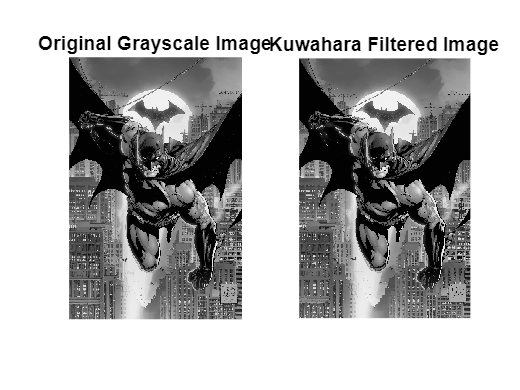

function output = kuwaharaFilter(img, ksize)
    if mod(ksize, 2) == 0
        error('Kernel size must be odd.');
    end
    
    
    padSize = floor(ksize/2);
    paddedImg = padarray(img, [padSize padSize], 'replicate', 'both');
    
    [rows, cols] = size(img);
    output = zeros(rows, cols); 

    
    for i = 1:rows
        for j = 1:cols
            
            center_i = i + padSize;
            center_j = j + padSize;

            
            sub1 = paddedImg(center_i-padSize:center_i-1, center_j-padSize:center_j-1);
            sub2 = paddedImg(center_i-padSize:center_i-1, center_j+1:center_j+padSize);
            sub3 = paddedImg(center_i+1:center_i+padSize, center_j-padSize:center_j-1);
            sub4 = paddedImg(center_i+1:center_i+padSize, center_j+1:center_j+padSize);

            
            means = [mean(sub1(:)), mean(sub2(:)), mean(sub3(:)), mean(sub4(:))];
            vars = [var(double(sub1(:))), var(double(sub2(:))), var(double(sub3(:))), var(double(sub4(:)))];

            
            [~, idx] = min(vars);

            
            output(i, j) = means(idx);
        end
    end

    
    output = uint8(255 * mat2gray(output));
end




img = imread('Bat.jpg'); 
gray_img = rgb2gray(img);
filtered_img = kuwaharaFilter(gray_img, 5);
figure;
subplot(1,2,1), imshow(gray_img), title('Original Grayscale Image');
subplot(1,2,2), imshow(filtered_img), title('Kuwahara Filtered Image');

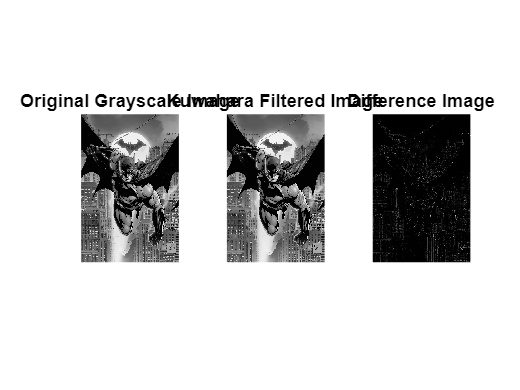

% Load the image one more time to check with the difference with kuwahara
img = imread('Bat.jpg');
gray_img = rgb2gray(img);
filtered_img = kuwaharaFilter(gray_img, 5); 
figure;
subplot(1,3,1), imshow(gray_img), title('Original Grayscale Image');
subplot(1,3,2), imshow(filtered_img), title('Kuwahara Filtered Image');
diff_img = abs(double(gray_img) - double(filtered_img));
subplot(1,3,3), imshow(diff_img, []), title('Difference Image');

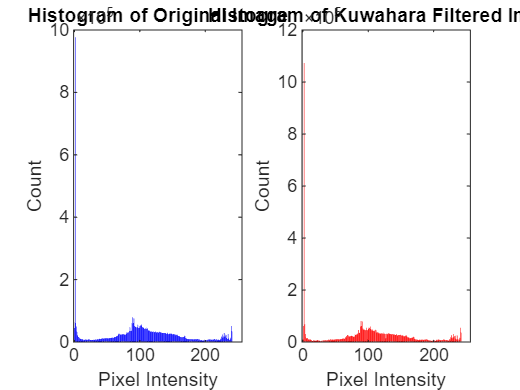

[hist_orig, orig_bins] = imhist(gray_img);
[hist_filt, filt_bins] = imhist(filtered_img);

figure;
subplot(1,2,1);
bar(orig_bins, hist_orig, 'b');
title('Histogram of Original Image');
xlabel('Pixel Intensity'); ylabel('Count');

subplot(1,2,2);
bar(filt_bins, hist_filt, 'r');
title('Histogram of Kuwahara Filtered Image');
xlabel('Pixel Intensity'); ylabel('Count');

disp('Histogram Values for Original Image:');

Histogram Values for Original Image:


disp([orig_bins, hist_orig]);

           0       45146
           1       61503
           2      976939
           3       50033
           4       32732
           5       21179
           6       16502
           7       15117
           8       12287
           9        9819
          10        9822
          11        8988
          12        9001
          13        9019
          14        6758
          15        6805
          16        7482
          17        7603
          18        7402
          19        6870
          20        6884
          21        7630
          22        8525
          23        7241
          24        6858
          25        6505
          26        6552
          27        6401
          28        6320
          29        6348
          30        6711
          31        7080
          32        7623
          33        7870
          34        7970
          35        8058
          36        8298
          37        8764
          38        9203
          39       10152


disp('Histogram Values for Kuwahara Filtered Image:');

Histogram Values for Kuwahara Filtered Image:


disp([filt_bins, hist_filt]);

           0        9691
           1       61515
           2     1072473
           3       67776
           4       30883
           5       16018
           6       13058
           7       14793
           8       11876
           9        8649
          10        9001
          11        8492
          12        9112
          13        8279
          14        4717
          15        4760
          16        5903
          17        6871
          18        6340
          19        5181
          20        5492
          21        6948
          22        8369
          23        6386
          24        5352
          25        4940
          26        4843
          27        4569
          28        3955
          29        4301
          30        4600
          31        5085
          32        6321
          33        6939
          34        6817
          35        6895
          36        6484
          37        6523
          38        7308
          39        8508
